作者：FallingIntoFall

链接：[量子力学用什么软件来求解主方程？ - 知乎](https://www.zhihu.com/question/24798426/answer/2231953068)

来源：知乎

著作权归作者所有。商业转载请联系作者获得授权，非商业转载请注明出处。


clear

Gamma_e = 2*pi*6; % dephasing rate of excited state |e>
Omega_e = 2*pi*15; % Rabi frequency of exciting field
Delta_e = 2*pi*4; % detuning of the |g>-|e> transition


% Optimized and vectorized two-level master equation solver in MATLAB
% Includes comments and removes unnecessary parts for clarity and efficiency


figure
% Hamiltonian for the two-level system
H = [0, Omega_e/2; Omega_e/2, Delta_e];

% Lindblad operator for decay from |e> to |g>
L = sqrt(Gamma_e) * [0 1; 0 0];
I = eye(2);

% Liouvillian superoperator construction (vectorized)
% The density matrix is reshaped as a column vector: rho(:)
% The master equation: drho/dt = -1i[H, rho] + L*rho*L' - 0.5*{L'*L, rho}

% Commutator part
H_comm = kron(I, H) - kron(H.', I);

% Lindblad dissipator part
L_diss = kron(conj(L), L) - 0.5*kron(I, L'*L) - 0.5*kron((L'*L).', I);

% Total Liouvillian
M = -1i*H_comm + L_diss;

% Time parameters
N = 1000;
t_total = 1;
dt = t_total/N;
T = linspace(0, t_total, N+1);

% Initial state: |g><g|
rho0 = [1;0]*[1,0];
rho_vec = rho0(:);

% Preallocate population array
rho_ee = zeros(size(T));

% Diagonalize Liouvillian for efficient propagation

历时 0.010256 秒。


U = expm(M * dt);

历时 0.003917 秒。


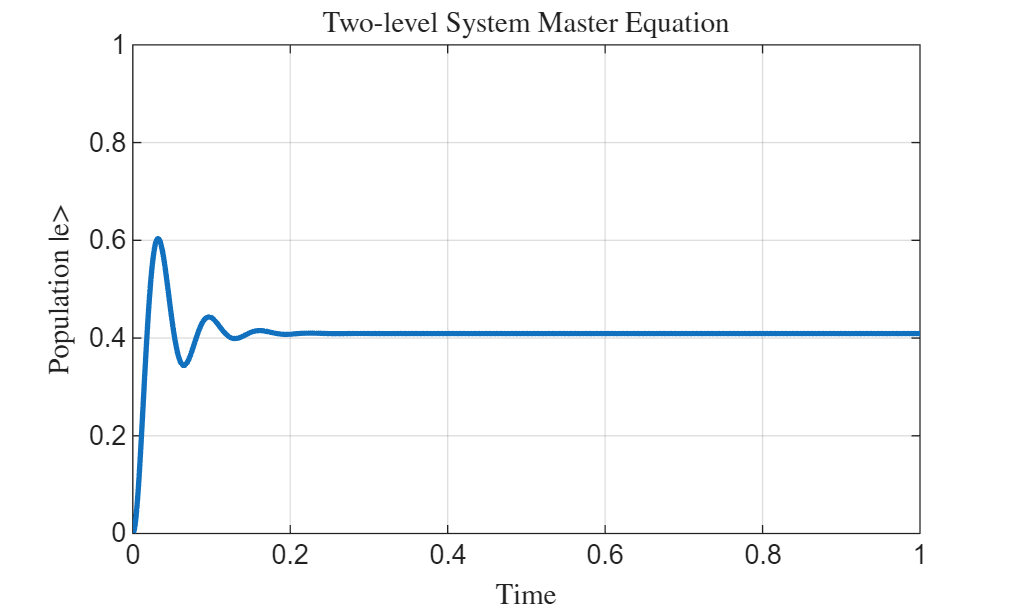

% Time evolution
for k = 1:length(T)
    rho_ee(k) = real(rho_vec(4)); % Population in |e>
    rho_vec = U * rho_vec;
end

% Plot excited state population
plot(T, rho_ee, 'LineWidth', 2);
xlabel('Time'); ylabel('Population |e>');
title('Two-level System Master Equation');
axis([0 t_total 0 1]); grid on;


% --- No need for P_JUST function due to vectorization ---
